# ELE632 - Lab 4

### Gabriel Casciano - 500744076

## A. Discrete-Time Fourier Transform (DTFT)

### 1)

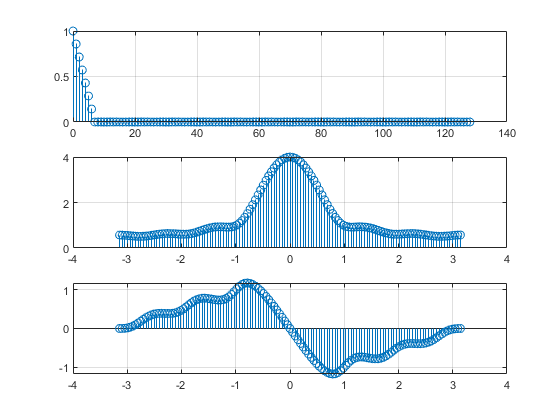

u = @(n) 1*(n>=0); 
x_1 = @(n) ((-1/7).*n + 1).*(n<=7) .* u(n);
n = 0:128;
ohm = -pi:(2*pi)/128:pi;

X_1 = fft(x_1(n));

subplot(3,1,1);
stem(n, x_1(n));
grid on;

subplot(3,1,2);
stem(ohm,fftshift(abs(X_1)));
grid on;

subplot(3,1,3);
stem(ohm, fftshift(angle(X_1)));
grid on;

### 2)

### 3)

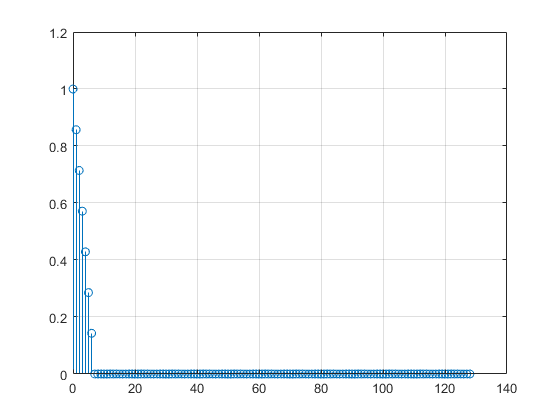

x = ifft(X_1);

subplot(1,1,1);
stem(n, abs(x));
grid on;

## B. Time Convolution

double check if you are supposed to use abs values of fft or the real value of fft (should the fft be negative at any point?)

### 1)

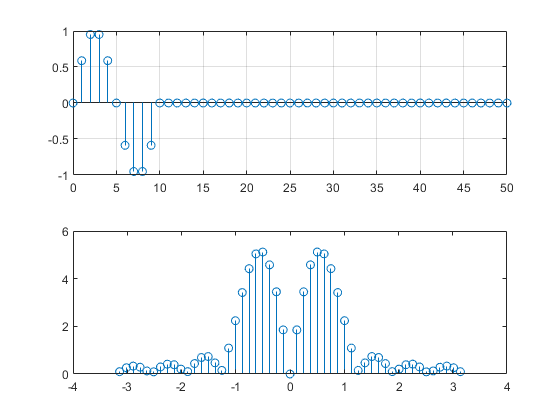

u = @(n) 1*(n>=0); 
x_2 = @(n) sin((2*pi.*n)/10).*(u(n) - u(n-10));

n = 0:50;

ohm = -pi:(2*pi)/(length(n)-1):pi;
X_2 = fft(x_2(n));

subplot(2,1,1);
stem(n, x_2(n));
grid on;

subplot(2,1,2);
stem(ohm, fftshift(abs(X_2)));

### 2)

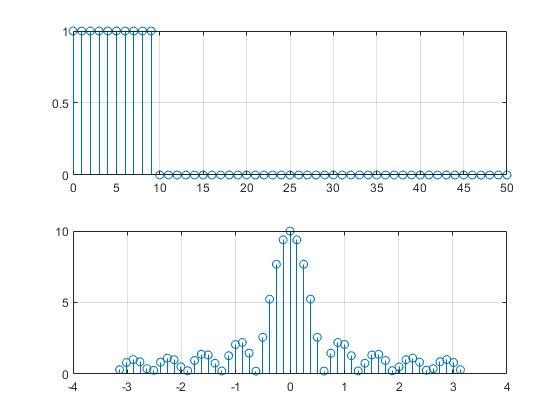

h = @(n) u(n) - u(n-10);

H = fft(h(n));

subplot(2,1,1);
stem(n, h(n));
grid on;

subplot(2,1,2);
stem(ohm, fftshift(abs(H)));
grid on;

### 3)

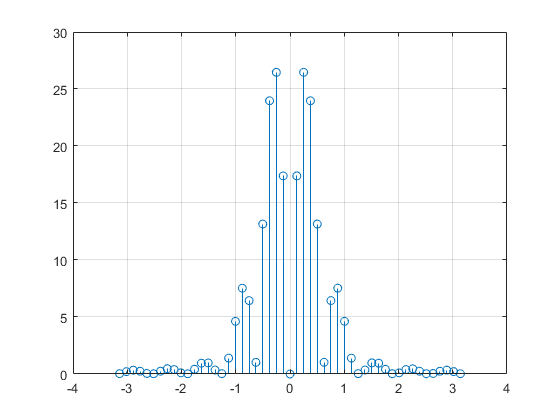

Y = H.*X_2;

y = ifft(Y);

subplot(1,1,1);
stem(ohm, fftshift(abs(Y)));
grid on;

### 4)

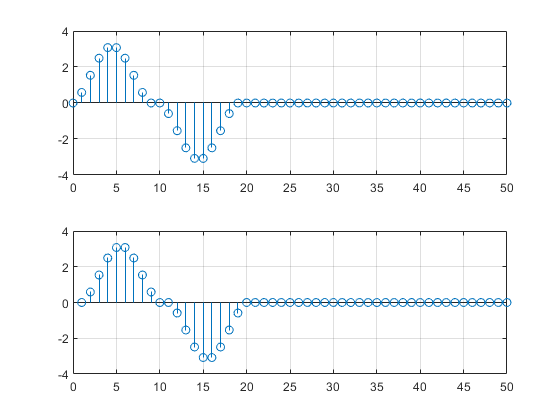

y_2 = conv(x_2(n), h(n));

subplot(2,1,1);
stem((0:length(y_2)-1),y_2);
grid on;
axis([0 50 -4 4])

subplot(2,1,2);
stem(y);
grid on;
axis([0 50 -4 4])

### 5)

Y_2 = fft(y);

ohm = -pi:(2*pi)/(length(y)-1):pi;

subplot(1,1,1);
stem(ohm, fftshift(abs(Y_2)));
grid on;

### 6)

The results from part 3 and 5 are identical, and that can be also compared in the time domain plot in part 4. This is also consistent with the properties of the fourier transform, as a multiplication in the frequency domain is as a convolution in the time domain.

## C) FIR Filter Design by Frequency Sampling

### 1)

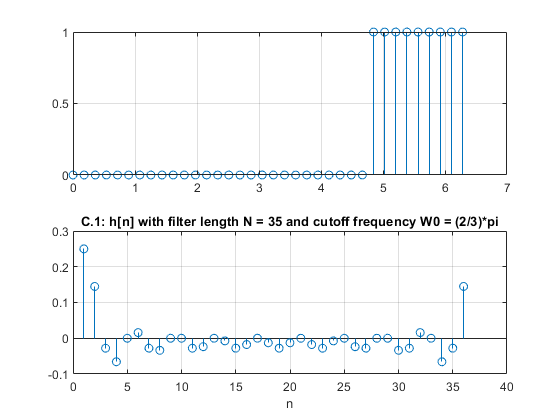

N = 35;
Omega = 0:(2*pi)/N:2*pi;

Ohm_o = (3*pi)/2;

H_d = @(ohm, Ohm_o) 1 - u(ohm + Ohm_o) + u(ohm - Ohm_o);

H = H_d(Omega, Ohm_o);

h = real(ifft(H));

subplot(2,1,1);
stem(Omega, real(H));
grid on;

subplot(2,1,2);
stem(real(h));
title('C.1: h[n] with filter length N = 35 and cutoff frequency W0 = (2/3)*pi');
xlabel('n');
grid on;

### 2)

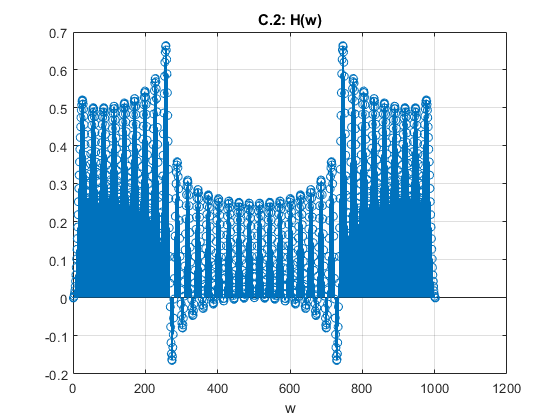

H = freqz(h,1,0:2*pi/1001:2*pi);

subplot(1,1,1);
stem(real(H));
title('C.2: H(w)');
xlabel('w');
grid on;

### 3)

The signal is still being allowed through with this rectangular filter, although on the inside of the cut-off frequency the signal carriers less power. An Ideal filter would block all frequencies outside of the high-pass band, and allow at full power all frequencies within the high-pass band.

### 4)

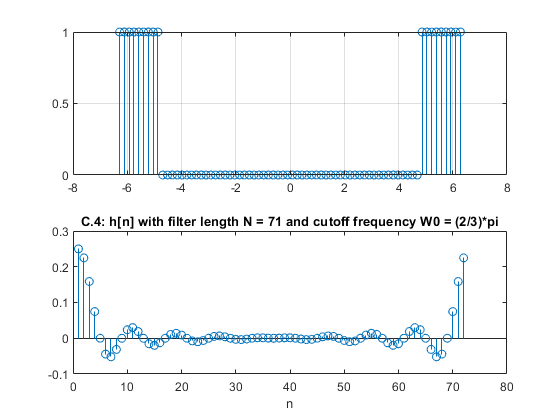

N = 71;
Omega = -2*pi:(4*pi)/N:2*pi;

Ohm_o = (3*pi)/2;

H_d = @(ohm, Ohm_o) 1 - u(ohm + Ohm_o) + u(ohm - Ohm_o);

H = H_d(Omega, Ohm_o);

h = real(ifft(H));

subplot(2,1,1);
stem(Omega, real(H));
grid on;

subplot(2,1,2);
stem(real(h));
title('C.4: h[n] with filter length N = 71 and cutoff frequency W0 = (2/3)*pi');
xlabel('n');

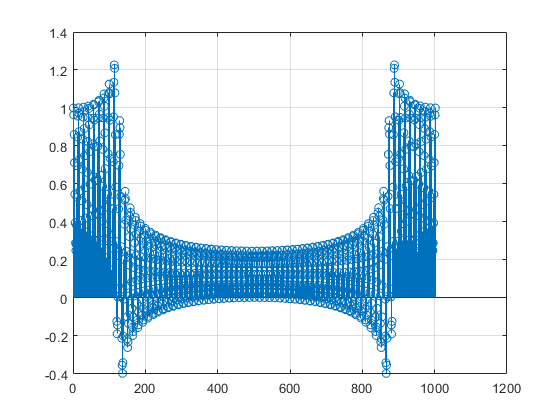

H = freqz(h,1,0:2*pi/1001:2*pi);

subplot(1,1,1);
stem(real(H));
grid on;

### 5)

As the value of $N
$ increases the approximation of the filter increases. As the $N$ increases the filter begins to perform more like an ideal filter, by comparing the frequency response of the 35 and 75 point filters we can see that the signals outside the high-pass band tend to zero sooner on the 75 point, but again are still passed through with reduced power. The signals within the high-pass band are allowed through at a much higher power compared to the lower point filter. I would assume that increasing N inifinitely woudl result in a perfect approximation of the ideal high-pass filter.